# Q1 Investigation

Find alphaQ1 from an analysis of tandem axles observed at WIM stations.

Produced using AxTandem, which comes from AxleStatsBasic.

*Can also use xAxTandem which comes from VBAxleStatsBasic - not as good*

Note the option to 'cap' at 18t, for example. However, we see that this doesn't make sense.

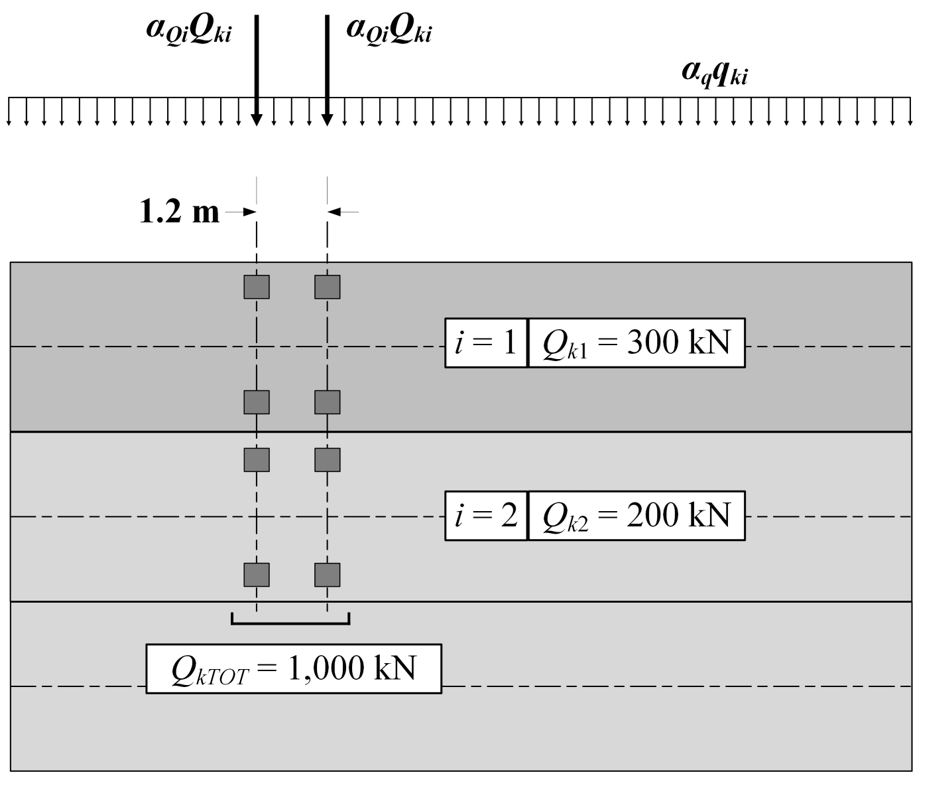

To save time, user can choose to skip the first 4 steps by loading AxTandemMax, AxTandempd, and AxTandemy_values.

In this case, the default Input values in Step 1 are used. Only available for AxTandem (not AxTandemx) with no cap.

% Initial commands
clear, clc, close all
% This function loads the variable 'AxTandem' which is produced by 'AxleStatsBasic'
load('AxTandem.mat')

### Step 1: Input desired filters/parameters

% Select which year to analyze %Years = 2011:2019;
Years = 0;
% Select stations (locations) to analyze %Stations = [408 409 405 406 402 415 416];
Stations = 0;

% Block Maxima (always use j)
BM = {'Daily', 'Weekly', 'Yearly'};

% Select which Classification you want to analyze (always use i)
ClassType = {'All', 'ClassOW', 'Class'};
% Must be in the order 'All' 'ClassOW' 'Class' due to deletions
ClassT = {'All', 'Classified+', 'Classified'};

### Step 2: Filter Axles based on desired year and station (location)

% Filter Axles based on desired year and station (location)
if Stations > 0
    y = AxTandem.ZST == Stations;
    AxTandem(~any(y,2),:) = [];
end
if Years > 0
    y = year(AxTandem.Time) == Years;
    AxTandem(~any(y,2),:) = [];
end
% Optional capping at 18t (not recommended)
% y = AxTandem.AWT1kN > 176.5197; AxTandem(y,:) = [];
% y = AxTandem.AWT2kN > 176.5197; AxTandem(y,:) = [];

### Step 3: Build Structure with Block Maxima

% Transform AxTandem into Array (necessary for splitapply)
Z = AxTandem;
Z.Time = datenum(Z.Time);
Z = table2array(Z);
            
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    % Filter based on Class - AxTandem is compromised after this (deleting entries)
    if strcmp(Class,'ClassOW')
        AxTandem(AxTandem.CLASS == 0,:) = [];
        Z(Z(:,5) == 0,:) = [];
    elseif strcmp(Class,'Class')
        AxTandem(AxTandem.CLASS == 0,:) = [];
        Z(Z(:,5) == 0,:) = [];
        AxTandem(AxTandem.CLASS > 39 & AxTandem.CLASS < 50,:) = [];
        Z(Z(:,5) > 39 & Z(:,5) < 50,:) = [];
    end
      
    for j = 1:length(BM)
        BlockM = BM{j};
        
        % Initialize
        Max.(Class).(BlockM) = [];
        
        if strcmp(BlockM,'Daily')
            
            % Make groups out of unique locations and days
            [Gr, GrIDDay, GrIDZST] = findgroups(dateshift(AxTandem.Time,'start','day'),AxTandem.ZST);
            
        elseif strcmp(BlockM,'Weekly')
            [Gr, GrIDWeek, GrIDZST] = findgroups(dateshift(AxTandem.Time,'start','week'),AxTandem.ZST);
        else
            [Gr, GrIDYear, GrIDZST] = findgroups(year(AxTandem.Time),AxTandem.ZST);
        end
        
        % Perform splitapply (see function at end... not just Max as we want whole rows involving maxes)
        Max.(Class).(BlockM) = splitapply(@(Z)maxIndex(Z),Z,Gr);
        % Transform back into table form
        Max.(Class).(BlockM) = array2table(Max.(Class).(BlockM));
        Max.(Class).(BlockM).Properties.VariableNames = {'Max','AWT1kN','AWT2kN','W1_2M','ZST','CLASS','Time'};
        Max.(Class).(BlockM).Time = datetime(Max.(Class).(BlockM).Time,'ConvertFrom',"datenum");
        
    end  
end

### Step 4: Curve Fitting

% Set Distribution Types
DistTypes = {'Normal', 'Lognormal', 'GeneralizedExtremeValue'};

% Set CDF Scaling Factors for estimates
D2WFactor = 5; W2YFactor = 50; D2YFactor = D2WFactor*W2YFactor;

% Set x values to be use globally
x_values = 0:1:800;

% Fit Block Maxima to Normal Curve
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        for k = 1:length(DistTypes)
            Dist = DistTypes{k};
   
            pd.(Class).(BlockM).(Dist) = fitdist(Max.(Class).(BlockM).Max/2,Dist);
            y_values.(Class).(BlockM).(Dist).PDF_Fit = pdf(pd.(Class).(BlockM).(Dist),x_values);
            y_values.(Class).(BlockM).(Dist).CDF_Fit = cdf(pd.(Class).(BlockM).(Dist),x_values);
            
            if strcmp(BlockM,'Daily')
                y_values.(Class).('Weekly').(Dist).CDF_D2W = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2WFactor;
                y_values.(Class).('Weekly').(Dist).PDF_D2W = [0 diff(y_values.(Class).('Weekly').(Dist).CDF_D2W)];
                y_values.(Class).('Yearly').(Dist).CDF_D2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_D2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_D2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                end

            elseif strcmp(BlockM,'Weekly')
                y_values.(Class).('Yearly').(Dist).CDF_W2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^W2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_W2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_W2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                end
            end
        end
    end
end

### Step 5: Plot Block Maxima

Comment the below inputs if we run the whole script

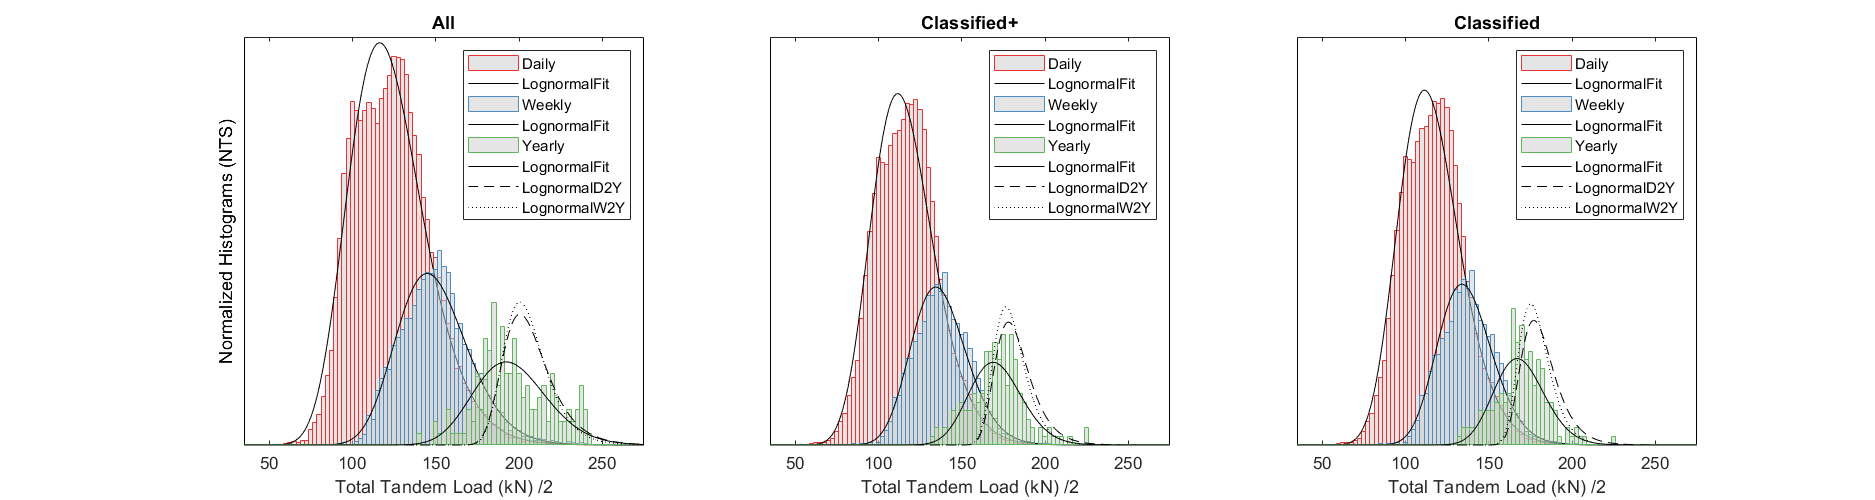

% Inputs
BM = {'Daily', 'Weekly', 'Yearly'};             % j
ClassType = {'All', 'ClassOW', 'Class'};        % i
ClassT = {'All', 'Classified+', 'Classified'};
DistTypes = {'Normal', 'Lognormal', 'GeneralizedExtremeValue'};
load('AxTandemMax.mat')
load('AxTandempd.mat')
load('AxTandemy_values.mat')
x_values = 0:1:800; % Must match those used to create y_values in Step 4

figure('Position',[0 0 1500 400]);

% Set colours
C = linspecer(9);
% ScaleDown
ScaleDown = [1 2.5 5];
% X Stuff
Step = 2.5;
LimitL = 10; LimitR = 300;
X = LimitL:Step:LimitR;
x = X(1:end-1) + diff(X);
    
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).Max/2,'BinEdges',X,'normalization','pdf');
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
        for k = 2
            Dist = DistTypes{k};
       
            plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])
            
            if strcmp(BlockM,'Yearly')
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_D2Y/ScaleDown(j),'k--','DisplayName',[Dist 'D2Y'])
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_W2Y/ScaleDown(j),'k:','DisplayName',[Dist 'W2Y'])
            end
        end
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+25 LimitR-25])
    if i == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('Total Tandem Load (kN) /2')
    title([ClassT{i}])
    legend('location','northeast')
end

#### *Block Maxima Compared between each other*

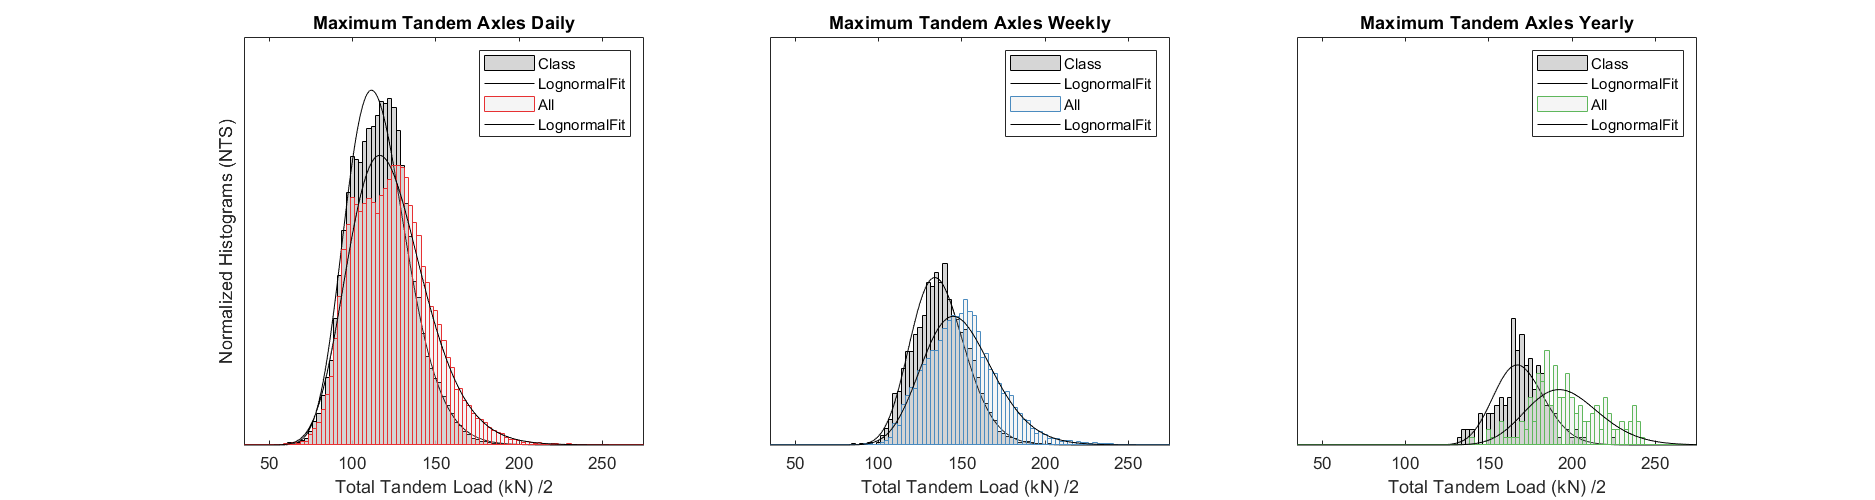

figure('Position',[0 0 1500 400]);

% X Stuff
Step = 2.5;
LimitL = 10; LimitR = 300;

for j = 1:length(BM)
    BlockM = BM{j};
    
    subplot(1,3,j)
    hold on
    k = 2;
    
    Class = 'Class';
    y = histcounts(Max.(Class).(BlockM).Max/2,'BinEdges',X,'normalization','pdf');
    bar(x,y/ScaleDown(j),1,'EdgeColor','k','FaceColor',[.8 .8 .8],'FaceAlpha',0.8,'DisplayName',Class)
    
    Dist = DistTypes{k};
    plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])    
    
    Class = 'All';
    y = histcounts(Max.(Class).(BlockM).Max/2,'BinEdges',X,'normalization','pdf');
    bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName',Class)
    
    Dist = DistTypes{k};
    plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])

    % Set Plot Details
    a = ylim;
    ylim([a(1) a(2)*j])
    box on
    set(gca,'ytick',[],'yticklabel',[])
    if j == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('Total Tandem Load (kN) /2')
    title(['Maximum Tandem Axles ' BlockM])
    legend('location','northeast')
    xlim([LimitL+25 LimitR-25])
    
end

#### *Block Maxima Compared for Classification Filters*

### Step 6: Probability Paper Plotting

When we apply the above equations, we are assuming the maximums are normally or log-normally distributed. We should evaluate the fit with a probability paper plot.

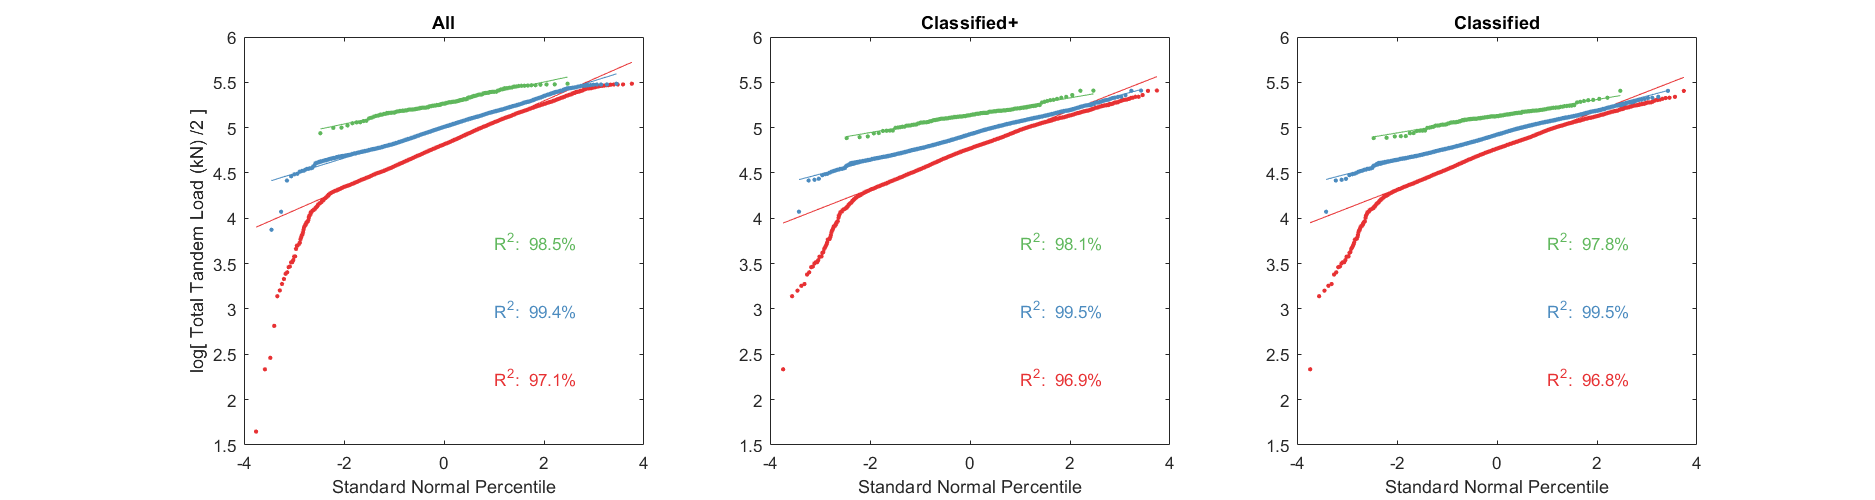

figure('Position',[0 0 1500 400]);
   
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    for j = 1:length(BM)
        BlockM = BM{j};
        subplot(1,3,i)
        hold on
        
        [MaxECDF, MaxECDFRank] = ecdf(Max.(Class).(BlockM).Max/2); MaxECDFRank = MaxECDFRank';  MaxECDF(1) = []; MaxECDFRank(1) = [];
        
        scatter(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),7,C(j,:),'filled','DisplayName','Max Data');
        mdl = fitlm(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),'linear');
        
        plot(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),mdl.Fitted,'-','Color',C(j,:),'DisplayName',['Fitted ' num2str(mdl.Rsquared.Ordinary,3)]);

        %text(1,y1(1)+(y1(2)-y1(1))/j,['\lambda = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(1)) '\zeta = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(2)) sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100)])

        box on
        xlim([-4 4])
        ylim([1.5 6])
        y1 = ylim;
        
        text(1,y1(1)+(y1(2)-y1(1))*(j/6),sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100),"Color",C(j,:))
        Fit(i,j) = mdl.Rsquared.Ordinary*100;
        
    end
        
    if i == 1
        ylabel('log[ Total Tandem Load (kN) /2 ]')
    end
    xlabel('Standard Normal Percentile')
    
    title([ClassT{i}])
    
end

#### *LogNormal Probability Paper*

### Step 7: $\alpha_{\textrm{Q1}}$ Estimates

*We account for the fact that the reliability index, *$\beta$, *must be for the same reference period as *$E_{m,\textrm{act}}$

Normal Distribution:                            $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \left\lbrack 1+\alpha \beta \nu \right\rbrack$

Lognormal Distribution:                      $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \exp \left\lbrack \alpha \beta \delta -0\ldotp 5\delta^2 \right\rbrack$      where         $\delta^2 =\ln \left(\nu^2 +1\right)$

% According to Annex C of SIA 269
Beta.Yearly = 4.7; % Here we use the Beta annual - so we should use annual max effects
Beta.Weekly = 5.44422; % See Tail Fitting > Beta Conversion
Beta.Daily = 5.72397;
Alpha = 0.7;

SumTableLogNormComp = array2table(zeros(1,(length(BM)-1)*length(ClassType)));
SumTableLogNormComp.Properties.RowNames = {'AlphaQ1LN'};
SumTableLogNormComp.Properties.VariableNames = {['W2Y ' ClassType{1}],['W2Y ' ClassType{2}],['W2Y ' ClassType{3}],['D2Y ' ClassType{1}],['D2Y ' ClassType{2}],['D2Y ' ClassType{3}]};

SumTableLogNorm = array2table(zeros(6,length(BM)*length(ClassType)));
SumTableLogNorm.Properties.VariableNames = {[BM{3} ' ' ClassType{1}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{3}], [BM{2} ' ' ClassType{1}],...
    [BM{2} ' ' ClassType{2}], [BM{2} ' ' ClassType{3}], [BM{1} ' ' ClassType{1}], [BM{1} ' ' ClassType{2}], [BM{1} ' ' ClassType{3}]};
SumTableLogNorm.Properties.RowNames = {'Em', 'Ed', 'Ed (%ile*10)', 'LNFit (%)', 'AlphaQ1N', 'AlphaQ1LN'};

for i = 1:length(ClassType)
    Class = ClassType{i};

    for j = 1:length(BM)
        BlockM = BM{j};
            
        Em = mean(Max.(Class).(BlockM).Max/2);
        Stdev = std(Max.(Class).(BlockM).Max/2);
        COV = Stdev/Em;
        Delta2 = log(COV^2+1);  
        Dist95N = norminv(0.95,pd.(Class).(BlockM).Normal.mu,pd.(Class).(BlockM).Normal.sigma);
        Dist95LN = logninv(0.95,pd.(Class).(BlockM).Lognormal.mu,pd.(Class).(BlockM).Lognormal.sigma);
        
        EdN = Em*(1+Alpha*Beta.(BlockM)*COV);
        AQN = EdN/(300*1.5);
        
        EdLN = Em*exp(Alpha*Beta.(BlockM)*sqrt(Delta2)-0.5*Delta2);
        AQLN = EdLN/(300*1.5);
        
        % Find %ile corresponding to Ed
        N5 = prctile(Max.(Class).(BlockM).Max/2,95);
    	I95 = invprctile(Max.(Class).(BlockM).Max/2,EdLN);
        
        SumTableLogNorm.([BlockM ' ' Class]) = [Em; EdLN; I95*10; Fit(i,j); AQN; AQLN];
        
        if strcmp(BlockM,'Weekly')
            pdx = pd.(Class).W2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Em = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['W2Y ' Class]) = [Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(300*1.5)];
        elseif strcmp(BlockM,'Daily')
            pdx = pd.(Class).D2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Em = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['D2Y ' Class]) = [Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(300*1.5)];
        end
    end
end

format bank
disp(SumTableLogNorm)

                    Yearly All    Yearly ClassOW    Yearly Class    Weekly All    Weekly ClassOW    Weekly Class    Daily All    Daily ClassOW    Daily Class
                    __________    ______________    ____________    __________    ______________    ____________    _________    _____________    ___________

    Em                195.90          171.05           169.10         149.52          137.44           136.84         122.82        116.20          115.97   
    Ed                281.02          231.27           225.69         256.27          216.61           214.26         255.41        217.81          216.12   
    Ed (%ile*10)

disp(SumTableLogNormComp)

                 W2Y All    W2Y ClassOW    W2Y Class    D2Y All    D2Y ClassOW    D2Y Class
                 _______    ___________    _________    _______    ___________    _________

    AlphaQ1LN     0.57         0.48          0.48        0.59         0.50          0.50   



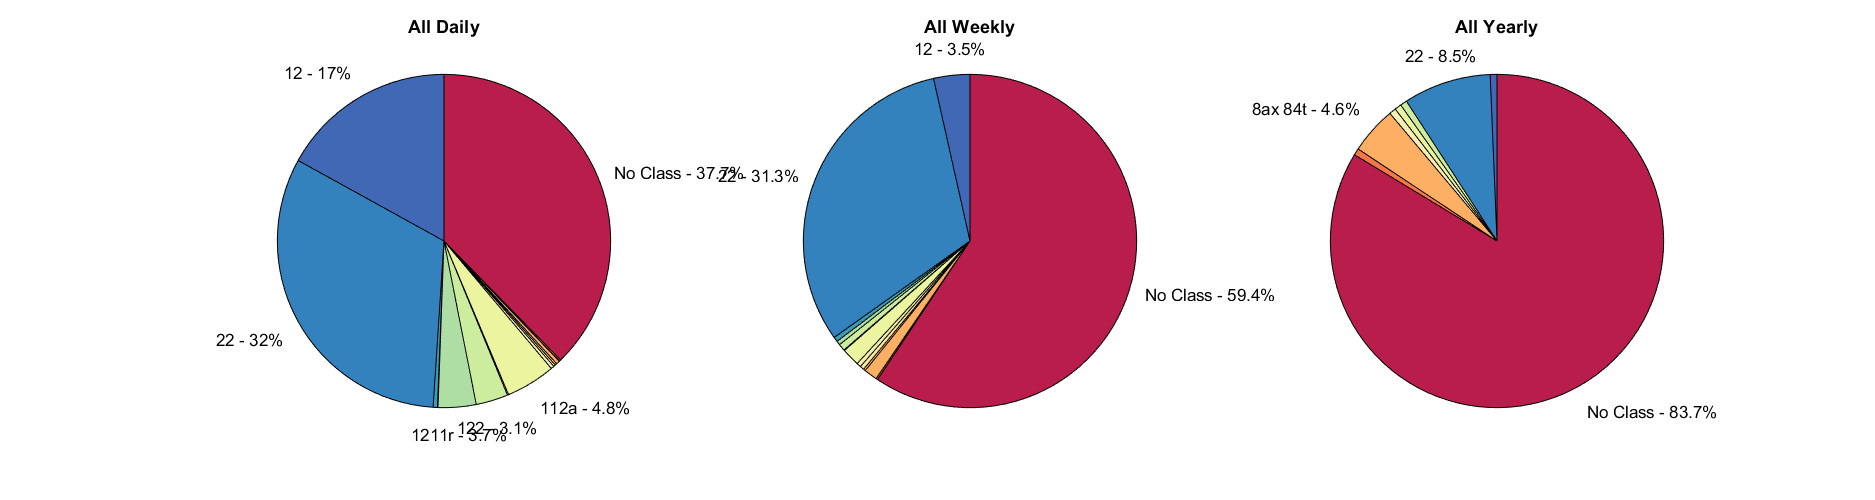

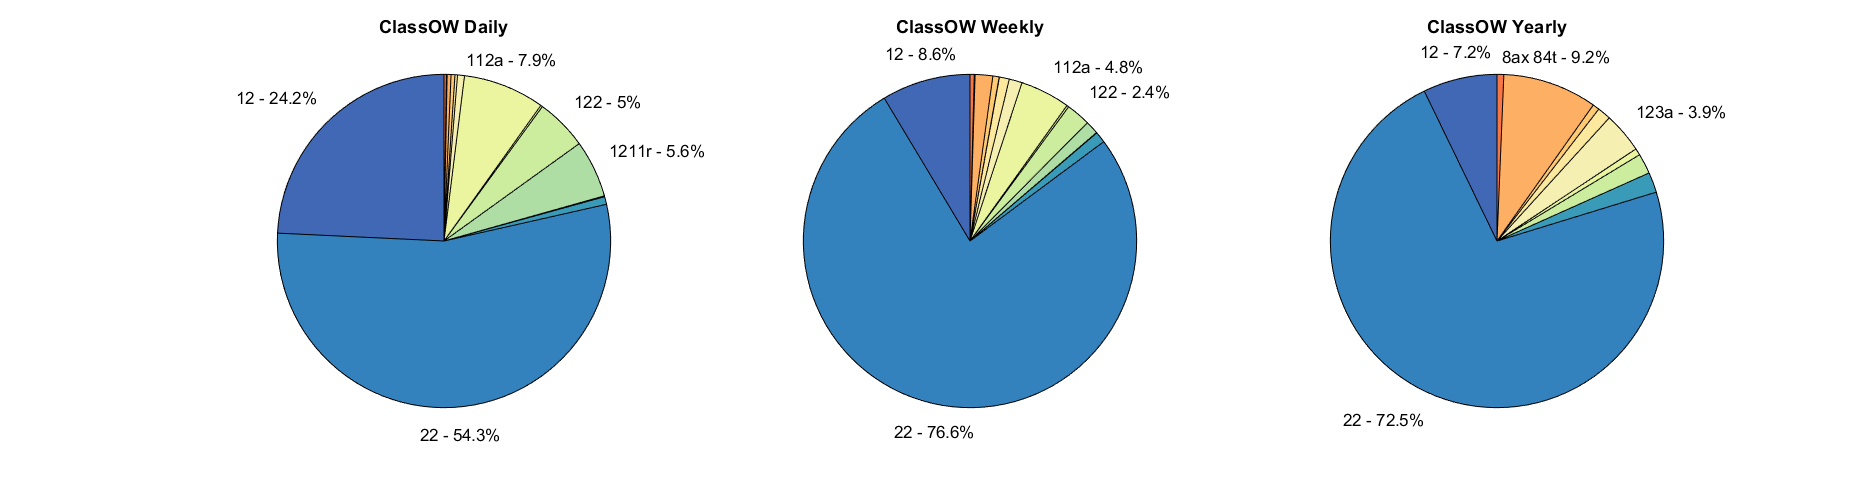

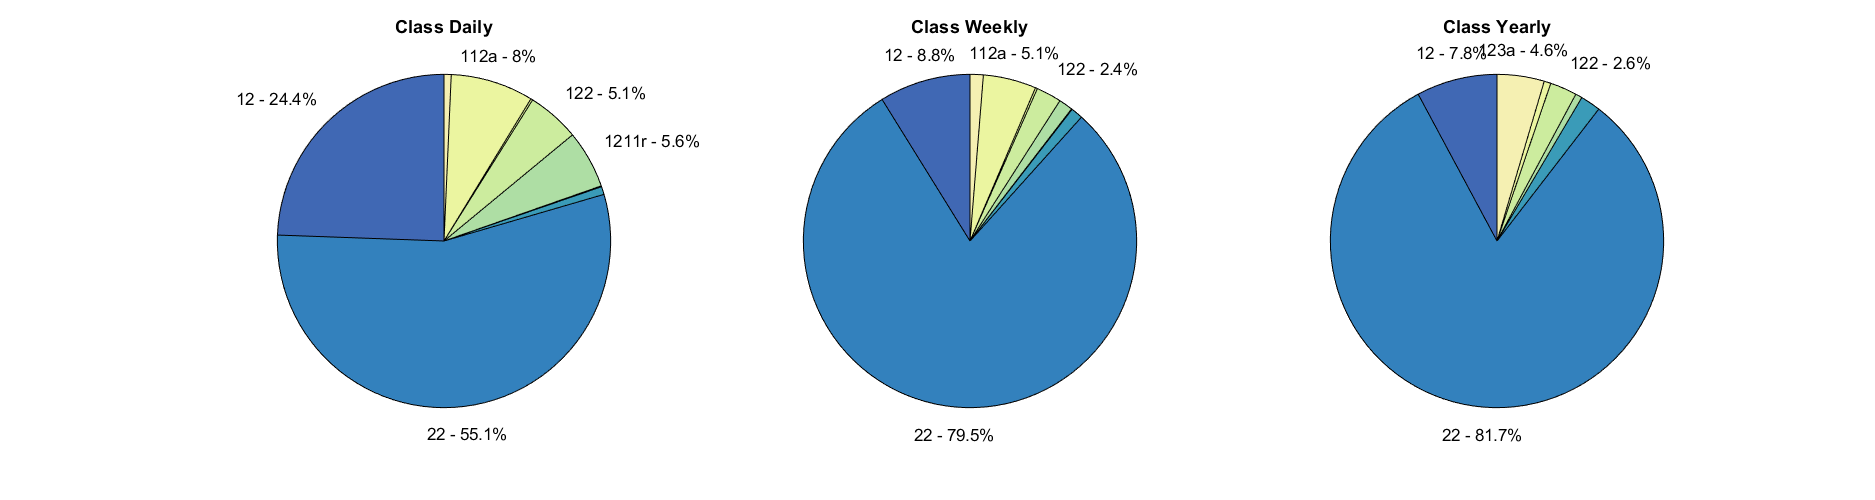

% What vehicles were involved?
TrTyps = [11; 12; 22; 23; 111; 11117; 1127; 12117; 122; 11127; 1128; 1138; 1238; 41; 42; 43; 44; 45; 46; 47; 48; 49; 0; 99];
TN = ["11" "12" "22" "23" "111" "1111r" "112r" "1211r" "122" "11112r" "112a" "113a" "123a"...
    "60t Crane" "6ax 60t" "7ax 72t" "8ax 84t" "9ax 96t" "96t Crane" "Libherr 132" "Libherr 15" "84t AT7" "No Class" "Empty"]';

% For each ClassType (or in this case just All and Class)
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    figure('Position',[0 0 1500 400]);
    hold on
    
    % Select Daily, Weekly, or Yearly
    for j = 1:length(BM)
        BlockM = BM{j};

        [N, Cats] = histcounts(categorical(Max.(Class).(BlockM).CLASS),categorical(TrTyps));
        
        Label = cell(length(TN),1);
        Perc = 100*N/sum(N);
        PercS = string(round(Perc,1))';
        
        for p = 1:length(TN)
            if Perc(p) > 2
                Label{p} = [TN{p} ' - ' PercS{p} '%'];  else;  Label{p} = '';
            end
        end
        
        % We need colors to be the same for each TrTyp
        % Labels should be strings that include the percentages
        subplot(1,3,j)
        title([Class ' ' BlockM],'fontweight','bold','fontsize',10);
        h = pie(N,Label);
        newColors = linspecer(numel(N));
        % Isolate the patch handles
        patchHand = findobj(h, 'Type', 'Patch');
        % Set the color of all patches using the nx3 newColors matrix
        set(patchHand, {'FaceColor'}, mat2cell(newColors, ones(size(newColors,1),1), 3))
        title([Class ' ' BlockM])
        
    end
end

#### Types of Vehicles Involved in Maximum Tandem Loads

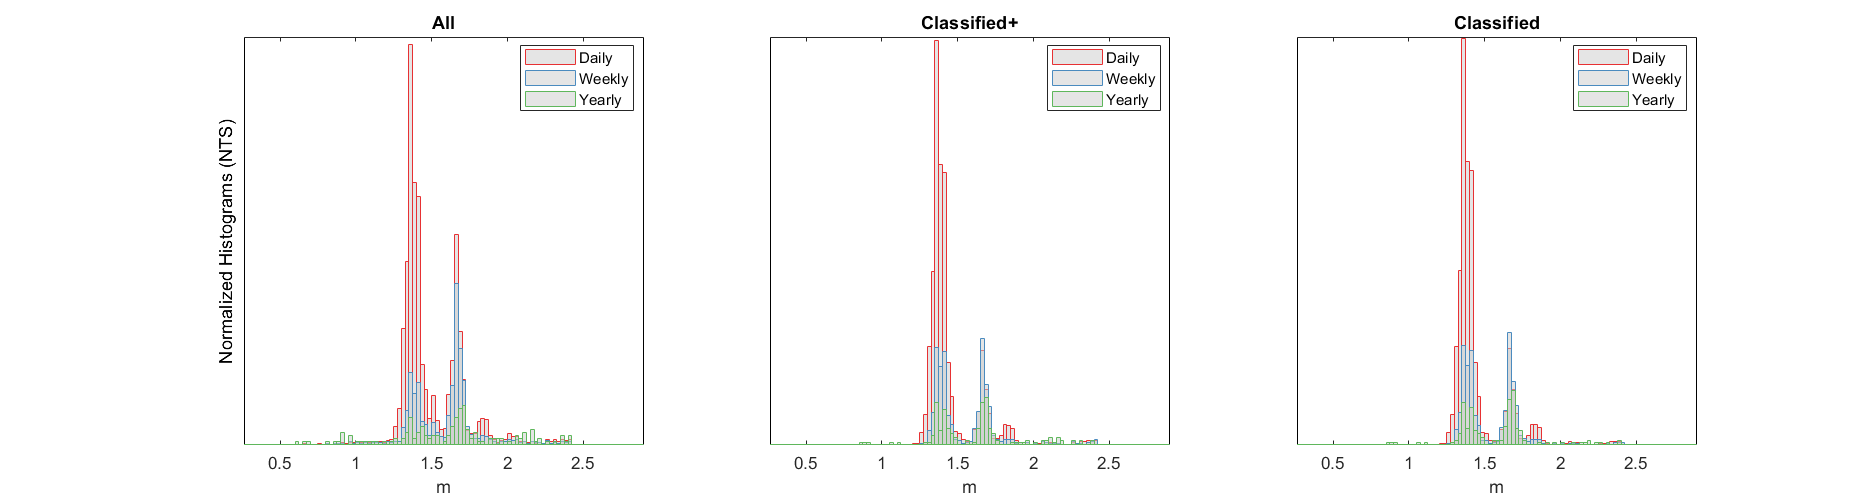

% What were the characteristics of those vehicles?
% Axle Spacing

figure('Position',[0 0 1500 400]);

% X Stuff
Step = 0.025;
LimitL = Step/2; LimitR = 3.15;
X = LimitL:Step:LimitR;
Xp = LimitL-Step/2:Step:LimitR-Step/2;
x = X(1:end-1) + diff(X);

for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).W1_2M,'BinEdges',X,'normalization','pdf');
        if i == 2 & strcmp(BlockM,"Weekly")
            ystar = Max.(Class).(BlockM).W1_2M;
        end
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+.25 LimitR-.25])
    if i == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('m')
    title([ClassT{i}])
    legend('location','best')
    %xticks(0.4:0.2:2.6)
end

#### *Axle Spacing (of Maxima) Comparison*

% % Muttoni suggestion - make above plots 2D scatter plots with weight on
% % Y-axis
% figure('Position',[0 0 1500 400]);
% 
% % X Stuff
% Step = 0.025;
% LimitL = Step/2;
% LimitR = 3.15;
% X = LimitL:Step:LimitR;
% Xp = LimitL-Step/2:Step:LimitR-Step/2;
% x = X(1:end-1) + diff(X);
% 
% for i = 1:length(ClassType)
%     Class = ClassType{i};
%     
%     subplot(1,3,i)
%     hold on
%     
%     for j = 1:length(BM)
%         BlockM = BM{j};
%         
%         y = histcounts(Max.(Class).(BlockM).W1_2M,'BinEdges',X,'normalization','pdf');
%         if i == 2 & strcmp(BlockM,"Weekly")
%             ystar = Max.(Class).(BlockM).W1_2M;
%         end
%         %bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
%         scatter(Max.(Class).(BlockM).W1_2M,Max.(Class).(BlockM).Max/2,'MarkerEdgeColor',C(j,:),'DisplayName',BlockM)
%     end
%     
%     % Set Plot Details
%     %set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
%     box on
%     xlim([LimitL+.25 LimitR-.25])
%     if i == 1
%         ylabel('Total Tandem Load (kN) /2')
%     end
%     xlabel('m')
%     title([ClassT{i}])
%     legend('location','best')
%     %xticks(0.4:0.2:2.6)
% end

#### *Scatter plots with weight and axle distance*

% Try with Gumbel Probability Paper

% for i = 1:length(ClassType)
%     Class = ClassType{i};
%     figure('Position',[0 0 1500 400]);
%     
%     for j = 1:length(BM)
%         BlockM = BM{j};
%         subplot(1,3,j)
%         hold on
%         
%         [MaxECDF, MaxECDFRank] = ecdf(Max.(Class).(BlockM).Max/2); MaxECDFRank = MaxECDFRank';
%         
%         scatter(MaxECDFRank,-log(-log(MaxECDF)),7,'k','filled','DisplayName','Max Data');
% 
%         box on
%         
%         ylabel('-log(-log(Probability of non-exceedance))')
%         xlabel('Total Tandem Load (kN) /2')
%         legend('location','best')
%         
%         title(['Maximum Tandem Axles ' BlockM])
%     end
% 
%     sgtitle(['Gumbel Probability Paper - ' Class ' Axles'],'fontweight','bold','fontsize',12);
%     
% end


% Reproducing Figure 3-3 from JRC Background Document to EN 1991 Part 2

% Q = 5:10:245;
% AllAx = [AxTandem.AWT1kN; AxTandem.AWT2kN];
% 
% AllAx(AllAx < 5) = [];
% xQ = sum(AllAx > Q)./length(AllAx);
% scatter(xQ,Q)
% set(gca, 'XScale', 'log')
% xlim([10^-8 10])c

#### Function(s)

function out = maxIndex(Z)
    [ymax, loc]=max(sum([Z(:,1) Z(:,2)],2));
    out=[ymax, Z(loc,:)];
end